## 1. feladat

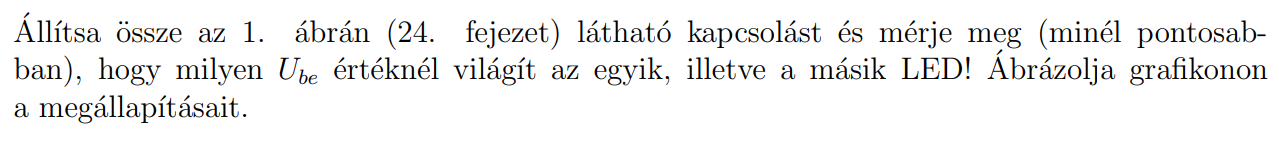

### Áramkör

[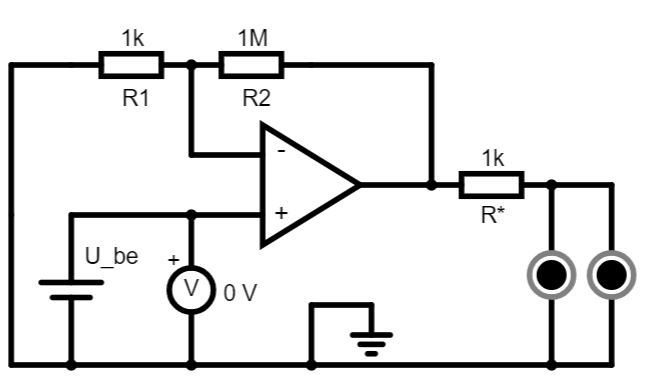](https://falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgBDEDA7tCXLmJ8IvVDRZJx8CTEjIwpAgkVpS1chUjCmYaARmGZyFIbYBzbgV5prV3vgg1IbAO4pkaELgwowA3xcANz8AmgUIfmcocAk9AyMjE2iYBDYADxRiGjUpOzVeCE8QAFUAfQAjBjdvIRFa4WRsqBrsLx8aXAIwlvdBRua2rOc2ACduLC8mnMJhmOl4Vtnp7lmeFvH1lYi58MX3VnbfQ92ak+3-U8ymmwQxAnoSEyKvACVcDKyxLFIUB7+vC8QK92Jk0D4UD9uGBKMgiOAUG80GdLlFVjYwCMAA7o6EzBy+egjdzrDqhbyBVr5fKTey9CZeWw2Wlklwk2ZkoassYNepdSL8eaLTK4BCUfgCLA5GEI4qvABUbCa7W6fNVnJAABMGAAzDgAVwANgAXJiGhialAxZywdjK8BNCk0MCOtCCrzavVG03my3ha22mr8p0O4Tcvqqt0QF3CKMtLreEAAMWSICYvl8LBAADUAPYmjjmapAA)

### Mérések

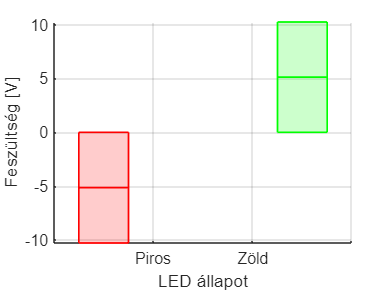

L_red = [-10.29 0];
L_green = [0 10.25];
Ranges = [L_red L_green];

boxchart([0 0 0.5 0.5] , [-10.29 0 0 10.25], 'GroupByColor', [0 0 1 1]); grid on;
xlabel('LED állapot');
ylabel('Feszültség [V]');
xticklabels({'', 'Piros','Zöld', ''});
ylim([L_red(1), L_green(2)])
colororder([1 0 0; 0 1 0]); 

## 2. feladat

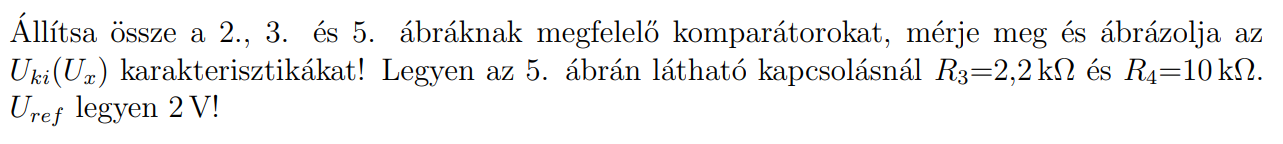

### 2. ábra

[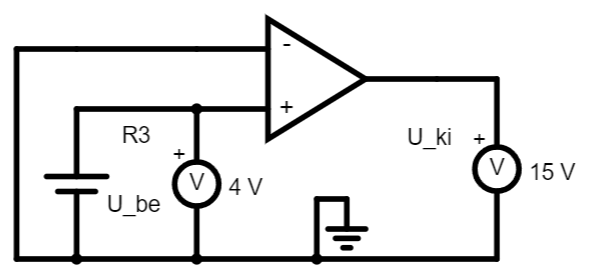](https://falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgBDEDA7tCXLmJ8IvZEhZJU8OFHAoZkNgHNuBXmnVre+CDSUB3FMjQhcGFGAEWlAN0vWayK9zD65b+e5gI2ADxRiGjRSKS0Q3ggTEABVAH0AIwY2I0FhNH4zYg1MpQDzYIRSMxcSUyjTeIBrAEsU7ixTAqydGzYABxaRLub6fXrWJotB7kIoAeieB1HePMCNBDECehJkeWiAJVwB0s8p-n7O-b2x3rlDGbNhl2aLzQ1wxu1xo2xTe4ah-tfTizer77TfZjKZKXA6EAAMTWNCYf1hawAagB7AA2ABcOMpkkA)

V_in = [ ...
    -10.29 -4.81 -1.054 -0.561 -0.0224 ...
    0.323 0.812 1.123 5.321  10.25 ...
];

V_out = [ ...
    -9.33 -9.33 -9.33 -9.33 -9.33 ...
    10.83 10.83 10.83 10.83 10.83 ...
];

measurements = table(V_in', V_out', ...
    'VariableNames', ["Bemeneti feszültség (V)", "Erősítő feszültsége (V)"]);
disp("Mért értékek");

Mért értékek


display(measurements);

measurements = 10×2 table
    Bemeneti feszültség (V)    Erősítő feszültsége (V)
    _______________________    _______________________

             -10.29                     -9.33         
              -4.81                     -9.33         
             -1.054                     -9.33         
             -0.561                     -9.33         
            -0.0224                     -9.33         
              0.323                     10.83         
              0.812                     10.83         
              1.123                     10.83         
              5.321                     10.83         
              10.25                     10.83         


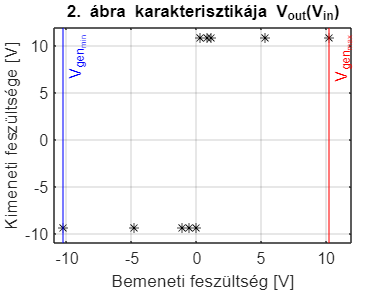


plot(V_in, V_out, "*k"); grid on;
title("2. ábra karakterisztikája V_{out}(V_{in})");
xlabel("Bemeneti feszültség [V]");
ylabel("Kimeneti feszültsége [V]");
xline(-10.29, "b", "V_{gen_{min}}");
xline(10.25, "r", "V_{gen_{max}}");
ylim([-11 12]);
xlim([-11 12]);

### 3. ábra

[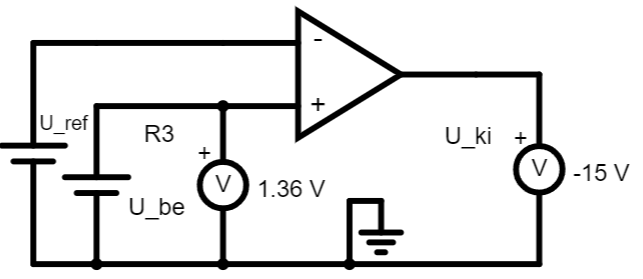](https://falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgBDEDA7tCXLmJ8IvZEhZJU8ONxTQhMpTPrT4bAObcCvNDu298EGpDYB3FMjQhcGFGAF3TAN3uOayB9zAmo4DwrEysH0vjAIbAAeKEHcpFL6aKS8EFYgAKoA+gBGDOY2QiI2xLr8UFE2dmgIpDZeJNap1lkA1gCW+djWtjRChk5sAA7FpQIllb1+phas1jxu3ITl0cjj1WIE9CTI4CjWAEq4+Z4Q-DTzZ+XDFz6L-ZMmnUs9Cy-TBh9dH+9ferpY3QGFnmLy+b2O9SWFyWLksgI8aXmvlu1jC0AiK3E3AQ1mQuFq1SQqRoWQATgwAGZsXCGEAAMR2NCYEAgLBAADUAPYAGwALhwNHkgA)

V_in = [ ...
    -10.29 -5.47 -2.95 -0.435 0.505  ...
    1.522 1.983 2.046 5.176 10.25
];

V_out = [ ...
    -9.33 -9.33 -9.33 -9.33 -9.33  ...
    -9.33 -9.29 10.85 10.85 10.85 
];

measurements = table(V_in', V_out', ...
    'VariableNames', ["Bemeneti feszültség (V)", "Erősítő feszültsége (V)"]);
disp("Mért értékek");

Mért értékek


display(measurements);

measurements = 10×2 table
    Bemeneti feszültség (V)    Erősítő feszültsége (V)
    _______________________    _______________________

            -10.29                      -9.33         
             -5.47                      -9.33         
             -2.95                      -9.33         
            -0.435                      -9.33         
             0.505                      -9.33         
             1.522                      -9.33         
             1.983                      -9.29         
             2.046                      10.85         
             5.176                      10.85         
             10.25                      10.85         


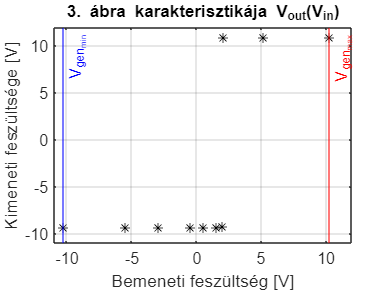


plot(V_in, V_out, "*k"); grid on;
title("3. ábra karakterisztikája V_{out}(V_{in})");
xlabel("Bemeneti feszültség [V]");
ylabel("Kimeneti feszültsége [V]");
xline(-10.29, "b", "V_{gen_{min}}");
xline(10.25, "r", "V_{gen_{max}}");
ylim([-11 12]);
xlim([-11 12]);

### 5. ábra

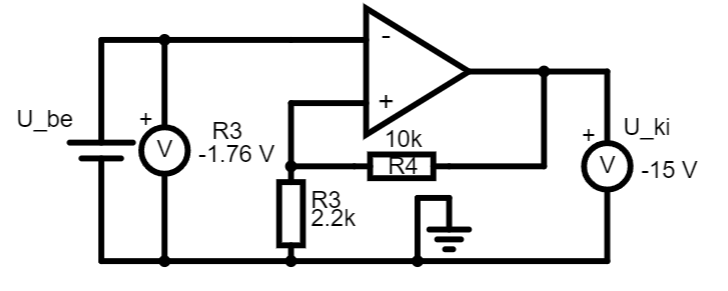

V_in_bj = [ ...
    -10.29 -6.1 -2.031 -0.033 0.202 ...
    1.098 1.811 1.914 5.04 10.25  ...
];

V_out_bj = [ ...
    10.61 10.61 10.61 10.61 10.61  ...
    10.61 10.61 -9.26 -9.26 -9.26  ...
];

V_in_jb = [ ...
    10.25 5.05 1.130 0.014 -1.1187  ...
    -1.623 -1.629 -3.2 -7.07 -10.29  ...
];

V_out_jb = [ ...
    -9.26 -9.26 -9.26 -9.26 -9.26  ...
    -9.26 10.61 10.61 10.61 10.61  ...
];

measurements = table(V_in_bj', V_out_bj', ...
    V_in_jb', V_out_jb', ...
    'VariableNames', ["Bemeneti feszültség balról jobbra (V)", "Erősítő feszültsége balról jobbra (V)", "Bemeneti feszültség jobbról balra (V)", "Erősítő feszültsége jobbról balra (V)"]);
disp("Mért értékek");

Mért értékek


display(measurements);

measurements = 10×4 table
    Bemeneti feszültség balról jobbra (V)    Erősítő feszültsége balról jobbra (V)    Bemeneti feszültség jobbról balra (V)    Erősítő feszültsége jobbról balra (V)
    _____________________________________    _____________________________________    _____________________________________    _____________________________________

                   -10.29                                    10.61                                     10.25                                   -9.26                
                     -6.1                                    10.61                                      5.05                                   -9.26                
                   -2.031                                    10.61                                      1.13                                   -9.26                
            

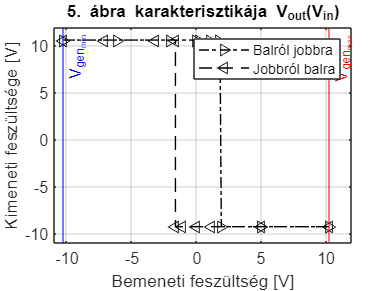


plot(V_in_bj, V_out_bj, "-.>k", V_in_jb, V_out_jb, "--<k"); grid on;
title("5. ábra karakterisztikája V_{out}(V_{in})");
xlabel("Bemeneti feszültség [V]");
ylabel("Kimeneti feszültsége [V]");
xline(-10.29, "b", "V_{gen_{min}}");
xline(10.25, "r", "V_{gen_{max}}");
legend(["Balról jobbra", "Jobbról balra"])
ylim([-11 12]);
xlim([-11 12]);

## 3. feladat

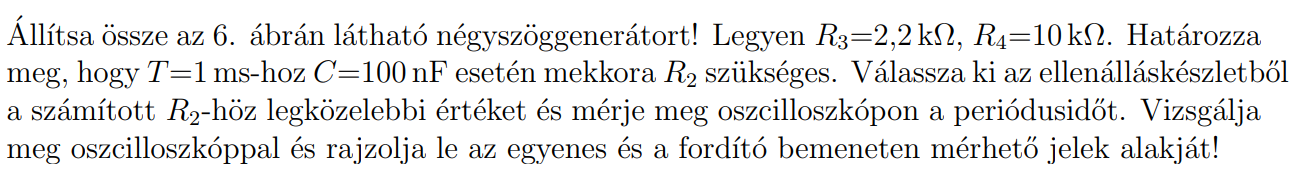

### Ábra

[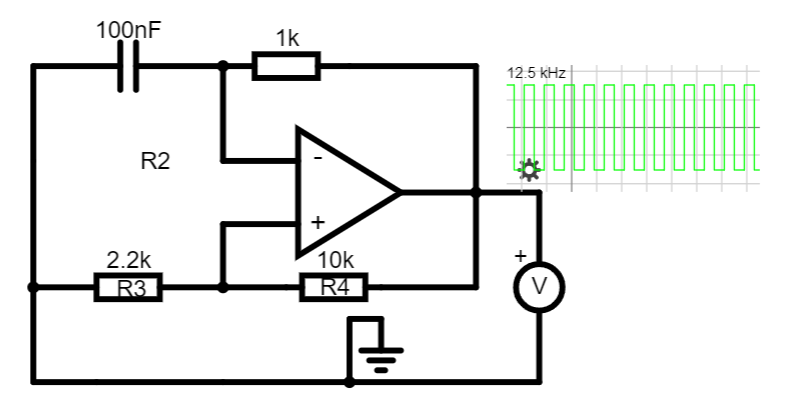](https://falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWK0CMBmNAOAbA7B2AJjDQTUgE4xCQEVbw1aBTAWhRQCgBDEQyTH2IgM2IREEok7JCnjwQrQrBQUsmfKUyZI2VYuX5IYNZDQVC5TAgQ4Qc+ZwDmfba8GE35CJCicA7vYoNGj89mAQob6QASJoYoTC8R7CMYGERCJhyVnRnAAOItgpkcW5fFB+6QLlKBHlae5NGTSego0tzZlRVXw1PZ09HTXEvvwemR1ug-F8k7GicyGziT6xo0t9EzQxAE58YGOZbZu+DnCcAB58CPhzCcf4FOD2NABKYJz745scrZNCC7XKQQDJ3FDYZ6eXwQYIgN5oL6-bBjGoQ6L2eBXezYBJwlCYeiEKQvOFvQicADGQRo6K2OIxKFg8hZLJQbDuykgqnUmlsOj0zyknEOTFItJR4B04kqCAA+ig5ZA5WAOMr+ErUHL2AqFiskrM6Y1FnTOkb1iNLZJJY0-gyafTbXCfnbOk7-rS4UNOEA)

### Számolás

T = 1 * 10^-3;
C = 100 * 10^-9;
R_3 = 2200;
R_4 = 10000;
alpha = R_3 / (R_3 + R_4);


$$\alpha =\frac{R_3 }{R_3 +R_4 }$$



$$\begin{array}{l}
T=4\cdot \;\alpha \cdot \;\;R_2 \cdot \;C\\
\frac{T}{4\cdot \;\alpha \cdot \;C}=R_2 
\end{array}$$


R_2 = T / (4 * alpha * C);


$$R_2 =13864\Omega \;$$


## 4. feladat

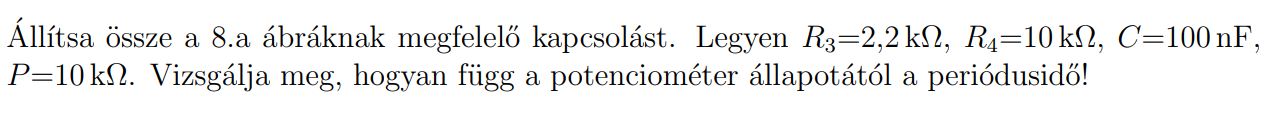

### Áramkör

[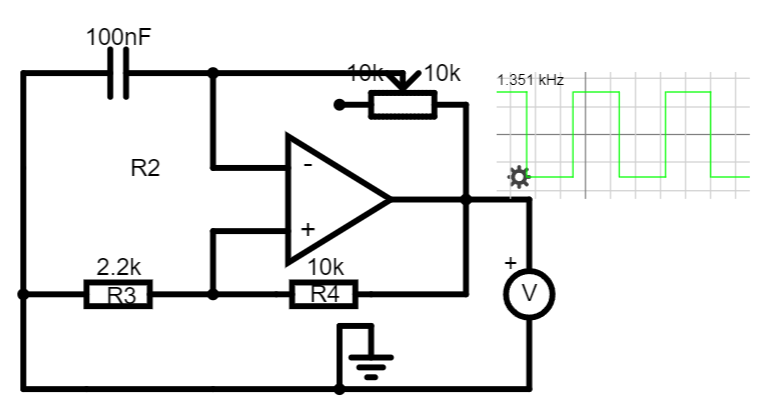](https://falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWK0wEYBMBmTD0E48B2dANjwA51VNwakw6BTAWlVQCgBDEdScn9BGwkBEfqiSskqePBCsUvEvlxwS5MHnQ9ohSJq1hSCBvjwiZs9gHMe5funt3+mfVCjsA7iDbbMvHzAhAMgvEGFRcPVI0O90YnCAzGj-SA8AByiHQSzEtO002J4+PMDgwrDHByd47SqPOIT62tKi3hcAltSG4ocwfJKWtpqEiKGwsdHkmMr+nibBhNCAJx45lualnysADx4EQnmRDcI8cB9tACUwdlX2+e1fB-d0XlC9iQh4w9QyOzSIBgQJdMOwPiRjkDUORUDwJOcgZd0OwAMY+KEkAbiTHuVCwWQEgmoFg-RSQZR4VTkjRaHwIdj9Gg4R44sDkfI5NIIAD66G5kG5aBkvIFMFQ3NY3I43jGOQiqEIIjagxV2Iq3ievzST3uRR1JR1SzChseQO6oQVXwSCpE8sVPmKchgSEujAAzgBLN0AF04ADsUYwJm4tb0fDjQkA)

### Mérések

R = [ ...
    8760 5980 3250 2210 880  ...
];

f = [ ...
    1.34*10^3 1.87*10^3 3.1*10^3 4.18*10^3 8*10^3  ...
];

T = 1./f;

measurements = table(R', f', T', ...
    'VariableNames', ["Ellenállás (Ohm)", "Frekvencia (1/s)", "Periódus idő (s)"]);
disp("Mért értékek");

Mért értékek


display(measurements);

measurements = 5×3 table
    Ellenállás (Ohm)    Frekvencia (1/s)    Periódus idő (s)
    ________________    ________________    ________________

          8760                1340             0.00074627   
          5980                1870             0.00053476   
          3250                3100             0.00032258   
          2210                4180             0.00023923   
           880                8000               0.000125   


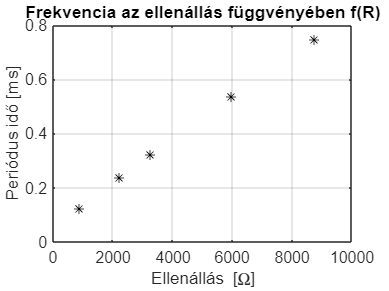


plot(R, T * 10^3, "*k"); grid on;
title("Frekvencia az ellenállás függvényében f(R)");
xlabel("Ellenállás [\Omega]");
ylabel("Periódus idő [ms]");

## 5. feladat

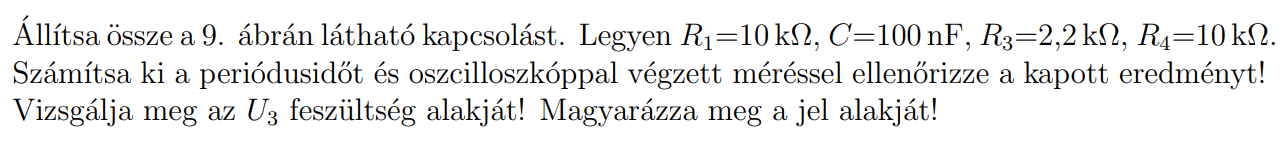

[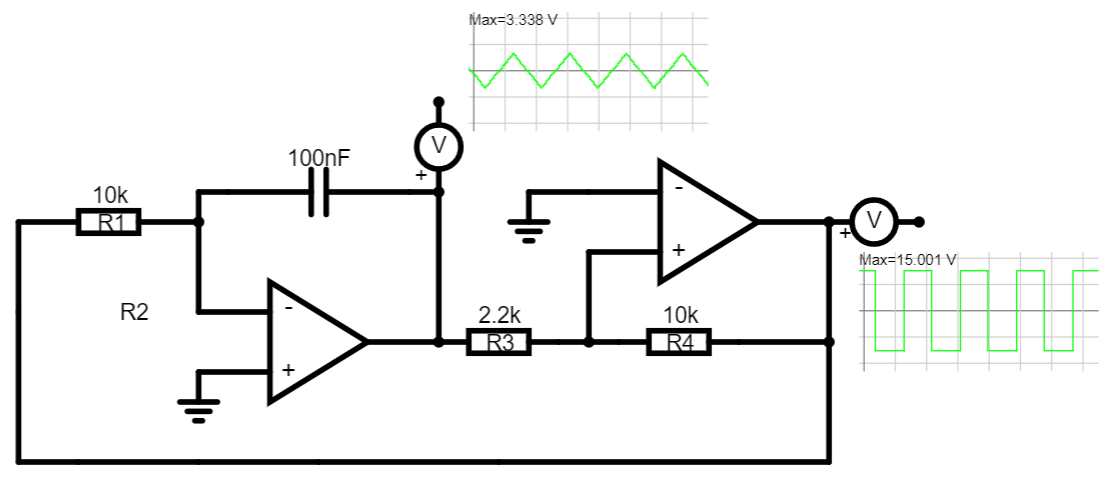](https://falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWK0wEYBMBmTD0E48B2dANjwA51VNwakw6BTAWlVQCgBDEdScn9BGwkBEfqiSskqePGSzUFEiQkIEkQmQIRIIGbPYBzHnx5hdvfugQjdkdgHc9GHuXFgI6N1Ec9ir-kwSK297J0sAvQ9IsJMQq38vfnsADz1lHhdUclRM+j10EAAldHYAY1EooV4qqD1YWUbG1BZCeqUSHDQya3VsvQRfCOHTVBI7XzZCsd0puJ8nOYil0K5wMfTdBGiZkHFJCT0mutRYTRtzNFJUS-FG32FKx5udB6DazBqXhcrv5ejYv9PKNxj40hIIGNpGR0vxIYUihwAE7zXZzXazAwo8wWQQgR7oPG4uDsNJBXKEvD4zQ8T7gArFTCk8AINqU8CJOnw4pgdjYvAiQkQBiFIUnAxObqVKWoGmxHHSjZi+VKvEiyqxbaQ0FajUPYKRXVJHzGTDkSHRM3auw-GWW821ewAB3x72+jwFPDqzpAut2CDw01BhQm5hoOEKYDh5FmLgseAA+mAE5Ak5AKAmZCnoKgE6xM+ww77QbKRMErOY6phU8ma+nyAneNnc-mOJLPWKjUTfF2IEbVkA)

R_1 = 10000;
C = 100 * 10^-9;
R_3 = 2200;
R_4 = 10000;
gamma = R_3 / R_4;


$$\gamma =\frac{R_3 }{R_4 }$$



$$T=4\cdot \;\gamma \cdot R_1 \cdot C\;$$


T = 4 * gamma * R_1 * C

T = 8.8000e-04

f = 1/T

f = 1.1364e+03


$$\begin{array}{l}
T=88\;\textrm{mS}\;\\
f=1136\textrm{Hz}
\end{array}$$


### Mérés


$$f=967\mathrm{Hz}$$


## 6. feladat

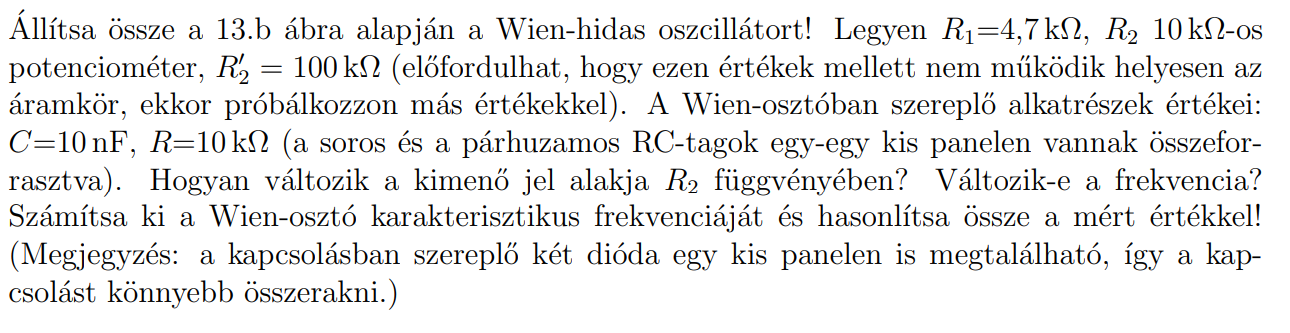

### Áramkör

[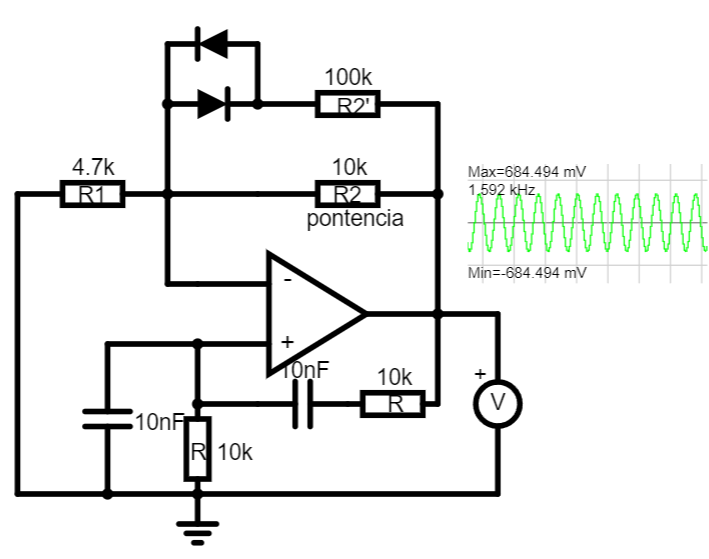](https://falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWK0AckDMBGTBOMOcA2SQgdgCYEdx0QkxaEBTAWmwCgBDEcyFH8hHTpCAiP0xI2STPHggWMSDhToUmNejClShBBkwKlKtQwR6EIyDLmR2AdxDZyIdLyfFX7u49783kB6BAVAOPHw8YIF+PBShjsKi5HGJYvGR0XExyS52AE48KPw5riKxuU5y7AAersqxoliksdQQmC4ASuwF2VkRIYGy8GHZEbguMT5OOBNjM0GhAMYZ5YXFcYOs-DDokGBU5Cg4mKT4hITHEEqQmDXhQpAT7XX0Tp0jEYKDnl9LC7+YTwDJxbIywEwoMwWKxIa63BJlciCVyEYrIqYxEIifzedgABxRaKEqK80Sg6VSSKEZUBgSmqVppVEzlCBQZPyiC0GVTZNOeAOe3Kqvk5LN+aFCABMVhLxiAJS5JUwAGacACuABsAC7saVysWi-kgJWqzU6xz6576zwY0Wea10sKWlxyiX5aYu+1Wm3gUhwJ3ewbPAZ3TBgNp6JxUDz8NqdW61Q7fJDkHAyElxkAdch3Q4uzDFAhvQyZ7MAcnYUVo6AQLvD4AVEUGpAA+igW5AWwxCOQW5hoJQO9BMC22H32ABzcI46L9MqOxPnJw6VwFpwSzN4gD2ADstUwd4sAJacdhqHiGABihiFt8CbCzTAAzken1rOIemOwgA)

### Számolás / mérés

R_1 = 4700;
R_2_p = 10000;
R_2 = 100000;
C = 10 * 10^-9;
R = 10000;

omega_zero = 1 / (R * C);
f_zero = omega_zero * 2 * pi;


$$\begin{array}{l}
\omega {\;}_0 =\frac{1}{R\cdot C}=\frac{1}{10\Omega \cdot {10}^3 \cdot 10F\cdot {10}^{-9} }=10000\frac{\textrm{rad}}{s}\\
f_0 =\omega {\;}_0 \cdot 2\pi =62832\textrm{Hz}
\end{array}$$


Mérés: $f=1\ldotp 55\mathrm{kHz}$

## 7. feladat (szorgalmi)

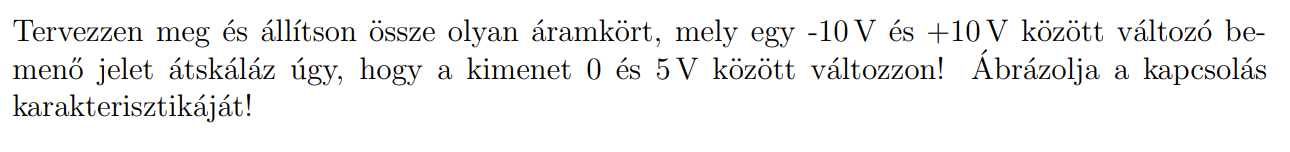

### Számítások

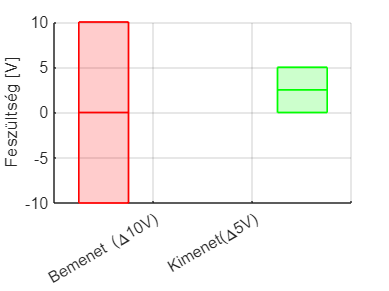

V_r_in = [-10 10];
V_r_out = [0 5];
Ranges = [V_r_in V_r_out];

boxchart([0 0 0.5 0.5], Ranges, 'GroupByColor', [0 0 1 1]); grid on;
ylabel('Feszültség [V]');
xticklabels({'', 'Bemenet (\Delta10V)','Kimenet(\Delta5V)'});
colororder([1 0 0; 0 1 0]); 

A bemeneti és kimeneti tartományokból megállapíthatjuk az erősítést:


$$\begin{array}{l}
\Delta \;V_{\mathrm{in}} =20V\\
\Delta \;V_{\mathrm{out}} =5V\\
\beta =\frac{V_{\mathrm{out}} }{V_{\mathrm{in}} }=0\ldotp 25
\end{array}$$


A legkisebb bemeneti jel és a legkisebb kimeneti jelből megállapíthatjuk az eltolást


$$\textrm{offset}=\min \left(V_{\textrm{out}} \right)-\min \left(V_{\textrm{in}} \right)=0V-\left(-10V\right)=10V$$



$$V_{\mathrm{offset}} =-\beta \cdot \mathrm{offset}=-2,5V$$



$$\begin{array}{l}
R_1 =R_2 =R=10k\Omega \;\\
R_4 =R=1k\Omega \;\\
R_3 =7R=7k\Omega \;
\end{array}$$


### Áramkör

[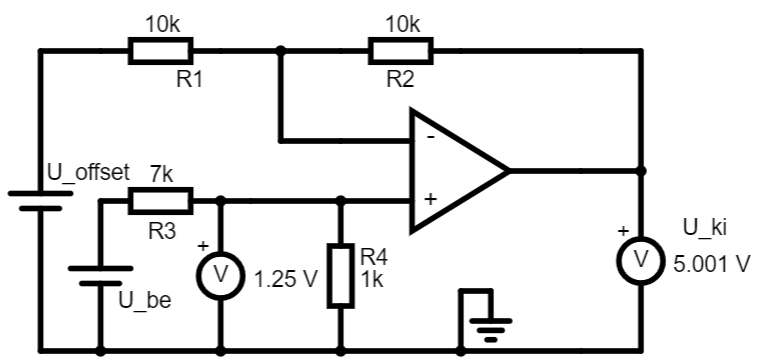](https://falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgBDENBY7tCLgIQ0AkARRwQLJKnhTk0HpFxYw5ZZGSyls+ZDYBzELlx80BCab74INAwHcQpGxhQWTbgwDd3Vt8geAvZQ4DSoofbQCGwAHiiq3BQoxEj4NBCBIACqAPoARgxsTkIiYmDI5mKO4JX8EBV8lfZxdBI8EmDEaNzEyODuObkA1gCWxZ40uG6lk1BsAA61VQ1101ORE7PNczsGAE67xDQ8TcehcnATopnnN9yE84fIpD07gRJ7kvATLinhHj2rW09BI4WI7WI9EyPQASrhgRCUFhSCgCPRkEQBllYex4hZwiikrIsTCQLC0FthP9ljSDEsXj1gihXnN6OEJozdh51vMSmZuJY5hYJDVeSK2V5rrxJVMpU4MO0wCcZcyalzxTLeQduKrlbrXCFLmxnkF9Vy1SAsD98cRzGpBf1sJQybCwNcxIqDQ9RdKzicxECnFydvcgyZqbzGnN1azmV61WxfH9eX8vhkaEw0NFIlBoq1yPxUcgwKDptienkAPYAMxrAGcGAAXNhCEwgABi-UzEQiLBAADUqwAbJscQxFIA)

### Mérés

V_in = [ ...
    -10.14 -8.03 -6.16 -4.13 -2.036  ...
    0.004 2.065 4.01 6.09 8.1 ...
    10.09 ...
];

V_out = [ ...
    0.028 0.555 1.023 1.530 2.056  ...
    2.569 3.084 3.56 4.08 4.58 ...=
    5.08
];

measurements = table(V_in', V_out', ...
    'VariableNames', ["Bemeneti feszültség (V)", "Erősítő feszültsége (V)"]);
disp("Mért értékek");

Mért értékek


display(measurements);

measurements = 11×2 table
    Bemeneti feszültség (V)    Erősítő feszültsége (V)
    _______________________    _______________________

            -10.14                      0.028         
             -8.03                      0.555         
             -6.16                      1.023         
             -4.13                       1.53         
            -2.036                      2.056         
             0.004                      2.569         
             2.065                      3.084         
              4.01                       3.56         
              6.09                       4.08         
               8.1                       4.58         
             10.09                       5.08         


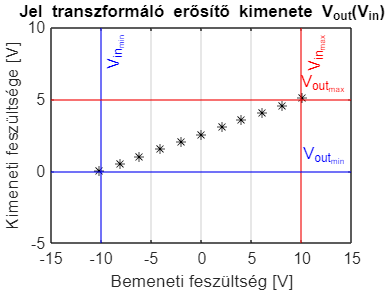


plot(V_in, V_out, "*k"); grid on;
title("Jel transzformáló erősítő kimenete V_{out}(V_{in})");
xlabel("Bemeneti feszültség [V]");
ylabel("Kimeneti feszültsége [V]");
xline(-10, "b", "V_{in_{min}}");
xline(10, "r", "V_{in_{max}}");
yline(0, "b", "V_{out_{min}}");
yline(5, "r", "V_{out_{max}}");
xlim([-15 15]);
ylim([-5 10]);